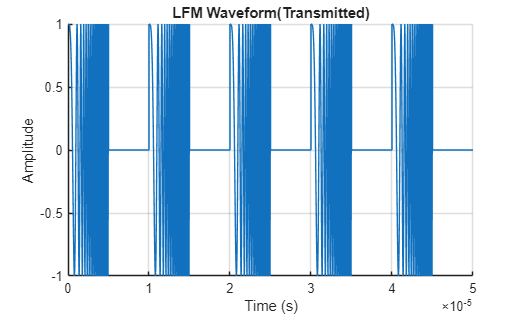

% First lets create an LFM wave form and plot it
clearvars;
clc;
t=0:1e-9:(50*10^(-6)-1e-9);
a = 1;
A=1;
fs=1/(1e-8);
b = 8 * 10^11;
phi=0;
c=3e8;
PRI=10^(-5);
PW=5*10^(-6);
velocity=300; %m/s
R=500;
Fc=10e8;
t_mod = mod(t, PRI);
hold on;
x = (t_mod >= 0 & t_mod < PW) .* exp(1j*(2*pi*(b/a)*(t_mod.^2) + phi));
plot(t, real(x));
grid on;
xlim([0,5*PRI]);
hold off;
title('LFM Waveform(Transmitted)');
xlabel('Time (s)');
ylabel('Amplitude');

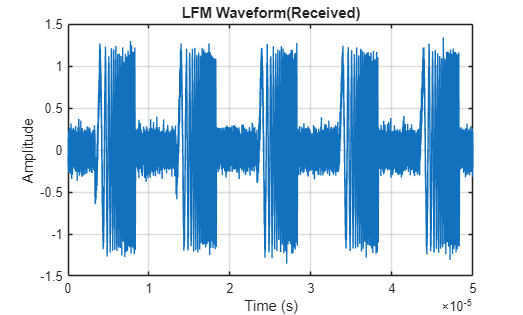

% Second Lets apply doopler carrier frequency shift, phase shift and lets
% add gaussian noise and plot return signal

carrier_frequency_shift=(2*velocity)/(c/Fc);
tau = 2 * R / c;
phi_shift = -2 * pi * Fc * tau;
t_delayed = t - tau;
t_mod_delayed = mod(t_delayed, PRI);
fd = (2 * velocity * Fc) / c;
pulse_envelope_delayed = A * (t_mod_delayed >= 0 & t_mod_delayed < PW);
x_r = pulse_envelope_delayed .* exp(1j*(2*pi * ((b/a) * (t_mod_delayed.^2)+carrier_frequency_shift*t) + phi + phi_shift));
noiseAmplitude = 0.1;
noise=noiseAmplitude.*(randn(1,length(t))+1j*randn(1,length(t)));
x_r=x_r+noise;
plot(t, real(x_r));
grid on;
xlim([0,5*PRI]);
hold off;
title('LFM Waveform(Received)');
xlabel('Time (s)');
ylabel('Amplitude');

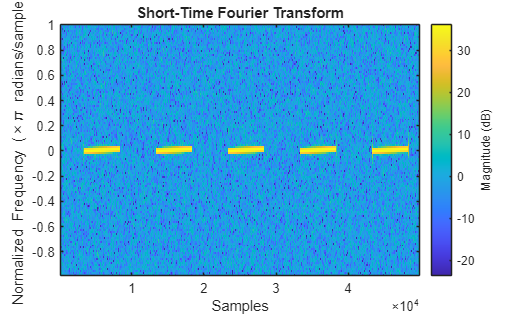

stft(x_r);
% for the doppler only 5 pulses is not enough  for determining range so
% lets redefine our LFM pulse so that it be 100 pulse apply matched filter for fast time
% and fft for the slow time:
t=0:1e-8:(50*20*10^(-6)-1e-9);
R=500;
tau = 2 * R / c;
M=100;
N=1e3;
t_mod = mod(t, PRI);
t_delayed = t - tau;
t_mod_delayed = mod(t_delayed, PRI);
phi_shift = -2 * pi * Fc * tau;
pulse_envelope_delayed = A * (t_mod_delayed >= 0 & t_mod_delayed < PW);
x = (t_mod >= 0 & t_mod < PW) .* exp(1j*(2*pi*(b/a)*(t_mod.^2) + phi));
x_r = pulse_envelope_delayed .* exp(1j*(2*pi * ((b/a) * (t_mod_delayed.^2)+carrier_frequency_shift*t)+ phi + phi_shift));
noiseAmplitude = 0.1;
noise=noiseAmplitude.*(randn(1,length(t))+1j*randn(1,length(t)));
x_r=x_r+noise;
%lets create data matrix slow time*fast time
Data_matrix_received=reshape(x_r, N, M).';
Data_matrix_transmitted=reshape(x,N,M).';
%lets apply matched filter to the matrix:
x_fft=zeros(M, 2*N-1, 'like', 1j);
x_m=zeros(M,2*N-1,'like',1j);
for k = 1:M
    x_m(k,:)=conv(Data_matrix_received(k,:),fliplr(conj(Data_matrix_transmitted(k,:))));
end
hold on

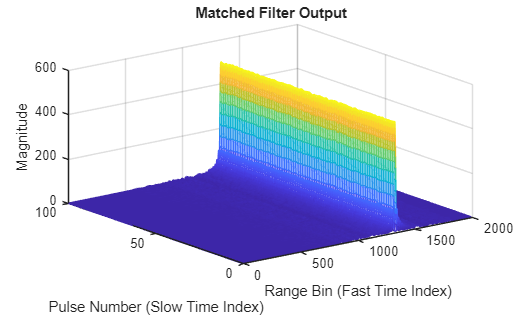

figure;
mesh(abs(x_m));
title('Matched Filter Output');
xlabel('Range Bin (Fast Time Index)');
ylabel('Pulse Number (Slow Time Index)');
zlabel('Magnitude');
hold off

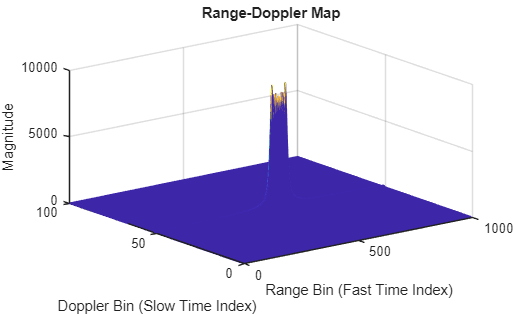



xx_fft=zeros(M, N, 'like', 1j);
for k=1:N
    xx_fft(:,k)=fft(Data_matrix_transmitted(:,k));
end
for k=1:M
    xx_fft(k,:)=fft(xx_fft(k,:));
end
xx_fft= fftshift(xx_fft);
figure;
mesh(abs(xx_fft));
hold on;
title('Range-Doppler Map');
xlabel('Range Bin (Fast Time Index)');
ylabel('Doppler Bin (Slow Time Index)');
zlabel('Magnitude');
hold off;

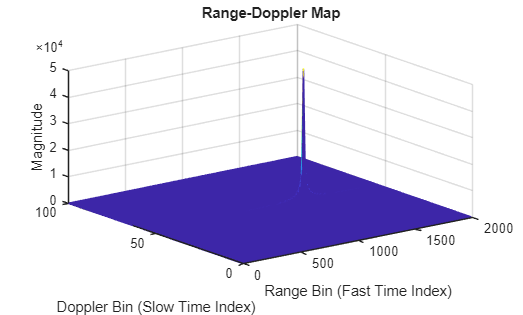



for k=1:2*N-1
    x_fft(:,k)=fft(x_m(:,k));
end
x_fft= fftshift(x_fft,1);
figure;
mesh(abs(x_fft));
hold on;
title('Range-Doppler Map');
xlabel('Range Bin (Fast Time Index)');
ylabel('Doppler Bin (Slow Time Index)');
zlabel('Magnitude');
hold off;

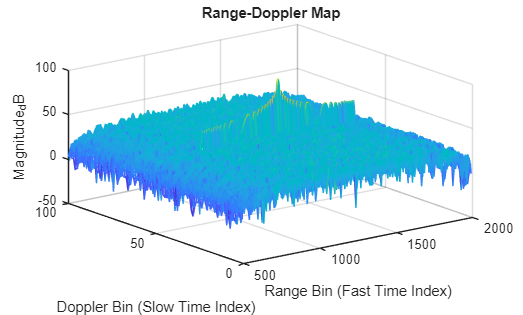

figure;
mesh(20*log10(abs(x_fft)));
hold on;
title('Range-Doppler Map');
xlabel('Range Bin (Fast Time Index)');
ylabel('Doppler Bin (Slow Time Index)');
zlabel('Magnitude_dB');
hold off;

%Lets calculate numerical results:
max_val = max(abs(x_fft), [], 'all');
[row, col] = find(abs(x_fft) == max_val);
% Calculate the estimated range and Doppler frequency
c=3e8;
f_d = (row-51) * (1 / (M * PRI));
estimatedRange =c*(col-N)/(2*fs);
estimatedDoppler =(f_d*c)/(2*Fc) ;
fprintf('Estimated Range: %.2f m\n', estimatedRange);

Estimated Range: 499.50 m


fprintf('Estimated Doppler velocity: %.2f m/s\n', estimatedDoppler);

Estimated Doppler velocity: 300.00 m/s
